%{

    run_1b_2.mlx
    ------------
    This code serves as the extension part to our stochastic life cycle model with endogenous labor supply.

%}
clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('/Users/nguyenhoangminh/Desktop/ps2 - task 1b'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is /Users/nguyenhoangminh/Desktop/ps2 - task 1b 




nu_vals = [0.5, 1.0, 1.5, 2.0];
gamma_fixed = 1.00;

% Load base model
par0 = model.setup();
par0 = model.gen_grids(par0);
ages = 1:par0.T;

fprintf('Descriptive stats by \\nu (\\gamma = %.2f):\n', gamma_fixed);

Descriptive stats by \nu (\gamma = 1.00):


fprintf(['  \\nu     | Mean(C)  Min(C)   Max(C)   Std(C)  || ' ...
                'Mean(A)  Min(A)   Max(A)   Std(A)\n' ...
                'Mean(N)  Min(N)   Max(N)   Std(N)']);

  \nu     | Mean(C)  Min(C)   Max(C)   Std(C)  || Mean(A)  Min(A)   Max(A)   Std(A)
Mean(N)  Min(N)   Max(N)   Std(N)

fprintf([repmat('-', 1, 83) '\n']);

-----------------------------------------------------------------------------------


figure(1); clf;

for i = 1:length(nu_vals)
    par = par0;
    par.nu = nu_vals(i);
    par.gamma = gamma_fixed;

    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    

    % Life-Cycle Profiles
    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);
    lcp_n = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), "omitnan");
        lcp_a(t) = mean(sim.asim(sim.tsim == t), "omitnan");
        lcp_n(t) = mean(sim.nsim(sim.tsim == t), "omitnan");
    end

    mean_c = mean(lcp_c, 'omitnan');
    min_c = min(lcp_c, [], 'omitnan');
    max_c = max(lcp_c, [], 'omitnan');
    std_c = std(lcp_c, 'omitnan');

    mean_a = mean(lcp_a, 'omitnan');
    min_a = min(lcp_a, [], 'omitnan');
    max_a = max(lcp_a, [], 'omitnan');
    std_a = std(lcp_a, 'omitnan');

    mean_n = mean(lcp_n, 'omitnan');
    min_n = min(lcp_n, [], 'omitnan');
    max_n = max(lcp_n, [], 'omitnan');
    std_n = std(lcp_n, 'omitnan');

    % Print results
    fprintf(' %.2f   | %.4f  %.4f  %.4f  %.4f  || %.4f  %.4f  %.4f  %.4f || %.4f  %.4f  %.4f  %.4f\n', ...
        par.nu, mean_c, min_c, max_c, std_c, ...
        mean_a, min_a, max_a, std_a,...
        mean_n, min_n, max_n, std_n);

    subplot(3,1,1); hold on;
    plot(ages, lcp_c, 'DisplayName', sprintf('\\nu = %.2f', par.nu));

    subplot(3,1,2); hold on;
    plot(ages, lcp_a, 'DisplayName', sprintf('\\nu = %.2f', par.nu));

    subplot(3,1,3); hold on;
    plot(ages, lcp_n, 'DisplayName', sprintf('\\nu = %.2f', par.nu));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 0.50   | 17.2141  5.6282  28.8414  6.8266  || 7.2005  0.0000  26.4452  6.2555 || 0.4904  0.0000  0.9899  0.3928


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 1.00   | 13.6064  2.8220  28.8069  8.9121  || 8.5454  0.0000  25.4693  6.5164 || 0.2693  0.0000  0.9469  0.2304


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 1.50   | 12.7799  2.2720  28.6255  9.2095  || 7.7275  0.0000  23.0083  6.1776 || 0.2231  0.0000  0.9735  0.1987


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 2.00   | 12.2014  2.1039  28.7648  9.4545  || 7.5612  0.0000  24.5624  6.3281 || 0.1951  0.0000  0.9780  0.1776


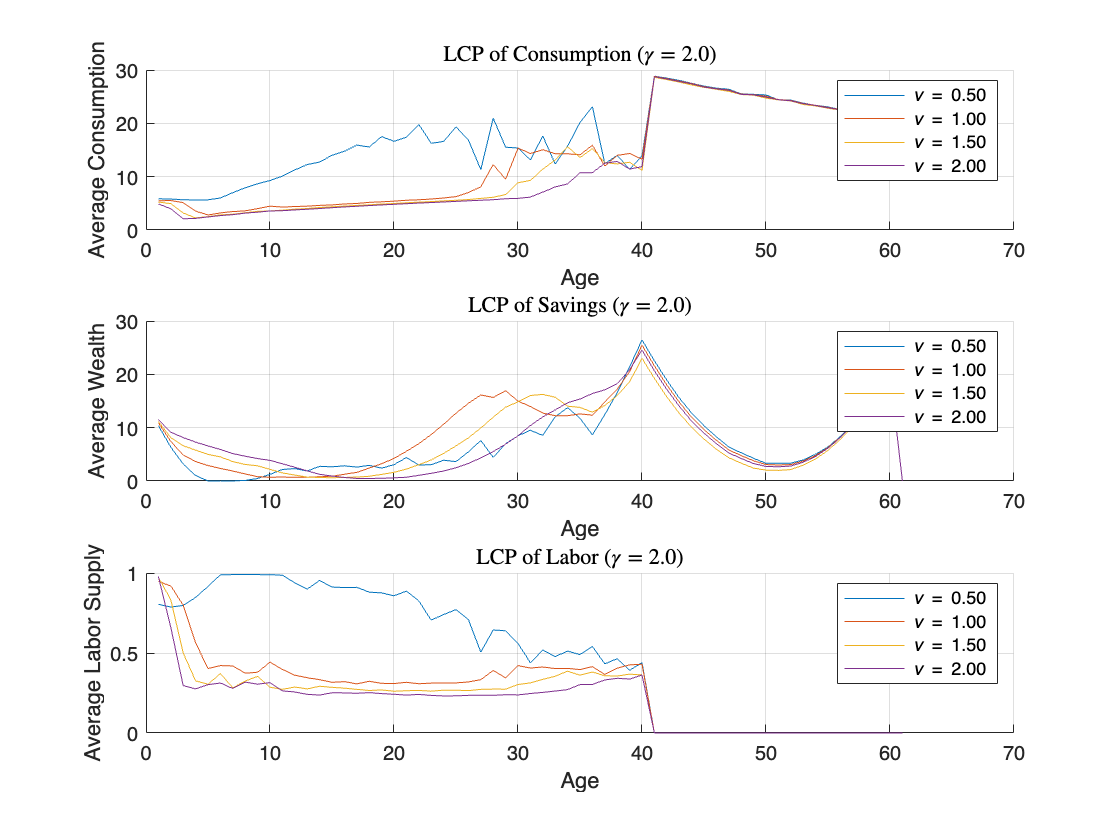

% Final plot touches for nu variation
subplot(3,1,1);
title('LCP of Consumption ($\gamma = 2.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Consumption'); grid on; legend show;

subplot(3,1,2);
title('LCP of Savings ($\gamma = 2.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Wealth'); grid on; legend show;
subplot(3,1,3);
title('LCP of Labor ($\gamma = 2.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Labor Supply'); grid on; legend show;


gamma_vals = [1.0, 2.0, 3.0, 4.0];
nu_fixed = 1.0;

% Load base model
par0 = model.setup();
par0 = model.gen_grids(par0);
ages = 1:par0.T;

fprintf('Descriptive stats by gamma (nu = %.2f):\n', nu_fixed);

Descriptive stats by gamma (nu = 1.00):


fprintf(['  gamma    | Mean(C)  Min(C)   Max(C)   Std(C)  || ' ...
                'Mean(A)  Min(A)   Max(A)   Std(A)\n']);

  gamma    | Mean(C)  Min(C)   Max(C)   Std(C)  || Mean(A)  Min(A)   Max(A)   Std(A)


fprintf([repmat('-', 1, 83) '\n']);

-----------------------------------------------------------------------------------


figure(1); clf;

for i = 1:length(gamma_vals)
    par = par0;
    par.gamma = gamma_vals(i);
    par.nu = nu_fixed;

    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    

    % Life-Cycle Profiles
    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);
    lcp_n = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), "omitnan");
        lcp_a(t) = mean(sim.asim(sim.tsim == t), "omitnan");
        lcp_n(t) = mean(sim.nsim(sim.tsim == t), "omitnan");
    end

    mean_c = mean(lcp_c, 'omitnan');
    min_c = min(lcp_c, [], 'omitnan');
    max_c = max(lcp_c, [], 'omitnan');
    std_c = std(lcp_c, 'omitnan');

    mean_a = mean(lcp_a, 'omitnan');
    min_a = min(lcp_a, [], 'omitnan');
    max_a = max(lcp_a, [], 'omitnan');
    std_a = std(lcp_a, 'omitnan');

    mean_n = mean(lcp_n, 'omitnan');
    min_n = min(lcp_n, [], 'omitnan');
    max_n = max(lcp_n, [], 'omitnan');
    std_n = std(lcp_n, 'omitnan');

    % Print results
    fprintf(' %.2f   | %.4f  %.4f  %.4f  %.4f  || %.4f  %.4f  %.4f  %.4f || %.4f  %.4f  %.4f  %.4f\n', ...
        par.nu, mean_c, min_c, max_c, std_c, ...
        mean_a, min_a, max_a, std_a,...
        mean_n, min_n, max_n, std_n);

    subplot(3,1,1); hold on;
    plot(ages, lcp_c, 'DisplayName', sprintf('\\gamma = %.2f', par.gamma));

    subplot(3,1,2); hold on;
    plot(ages, lcp_a, 'DisplayName', sprintf('\\gamma = %.2f', par.gamma));

    subplot(3,1,3); hold on;
    plot(ages, lcp_n, 'DisplayName', sprintf('\\gamma = %.2f', par.gamma));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 1.00   | 13.6064  2.8220  28.8069  8.9121  || 8.5454  0.0000  25.4693  6.5164 || 0.2693  0.0000  0.9469  0.2304


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 1.00   | 14.4533  2.3084  28.7254  8.9592  || 10.2603  0.0000  25.0593  5.8321 || 0.3007  0.0000  0.9740  0.2573


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 1.00   | 14.8481  1.7110  28.8920  8.9996  || 10.8733  0.0000  26.3307  5.8577 || 0.3123  0.0000  0.9782  0.2555


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 1.00   | 15.0494  1.7893  28.7019  9.0554  || 10.4722  0.0000  24.7379  6.0646 || 0.3214  0.0000  0.9790  0.2616


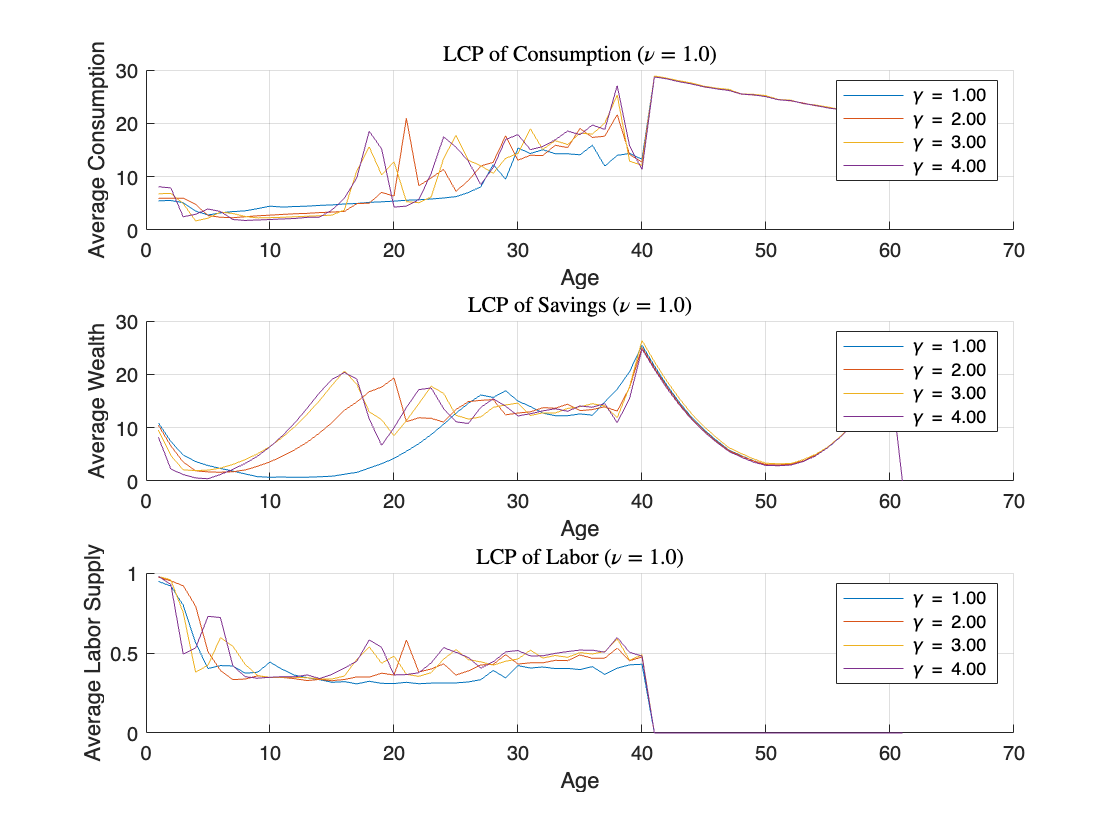

% Final plot touches for nu variation
subplot(3,1,1);
title('LCP of Consumption ($\nu = 1.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Consumption'); grid on; legend show;

subplot(3,1,2);
title('LCP of Savings ($\nu = 1.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Wealth'); grid on; legend show;

subplot(3,1,3);
title('LCP of Labor ($\nu = 1.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Labor Supply'); grid on; legend show;

real_data = readtable('real_data_22.csv', 'VariableNamingRule', 'preserve');

ages_real = real_data.m1ac5 - 24;
valid_idx = ages_real <= 61;

wealth_real = real_data.('Value of Household Asset');
cons_real = real_data.('Average Annual Consumption - All Categories');
labor_real = real_data.('Average Household Working Hours');
labor_real(ages_real >= 41) = 0;
wealth_real_norm = wealth_real / wealth_real(1);
cons_real_norm = cons_real / cons_real(1);

ages_real_trimmed = ages_real(valid_idx);
wealth_real_trimmed = wealth_real_norm(valid_idx);
cons_real_trimmed = cons_real_norm(valid_idx);
labor_real_trimmed = labor_real(valid_idx);

par0 = model.setup();
par0 = model.gen_grids(par0);
ages = 1:par0.T;
sol = solve.lc(par0);

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


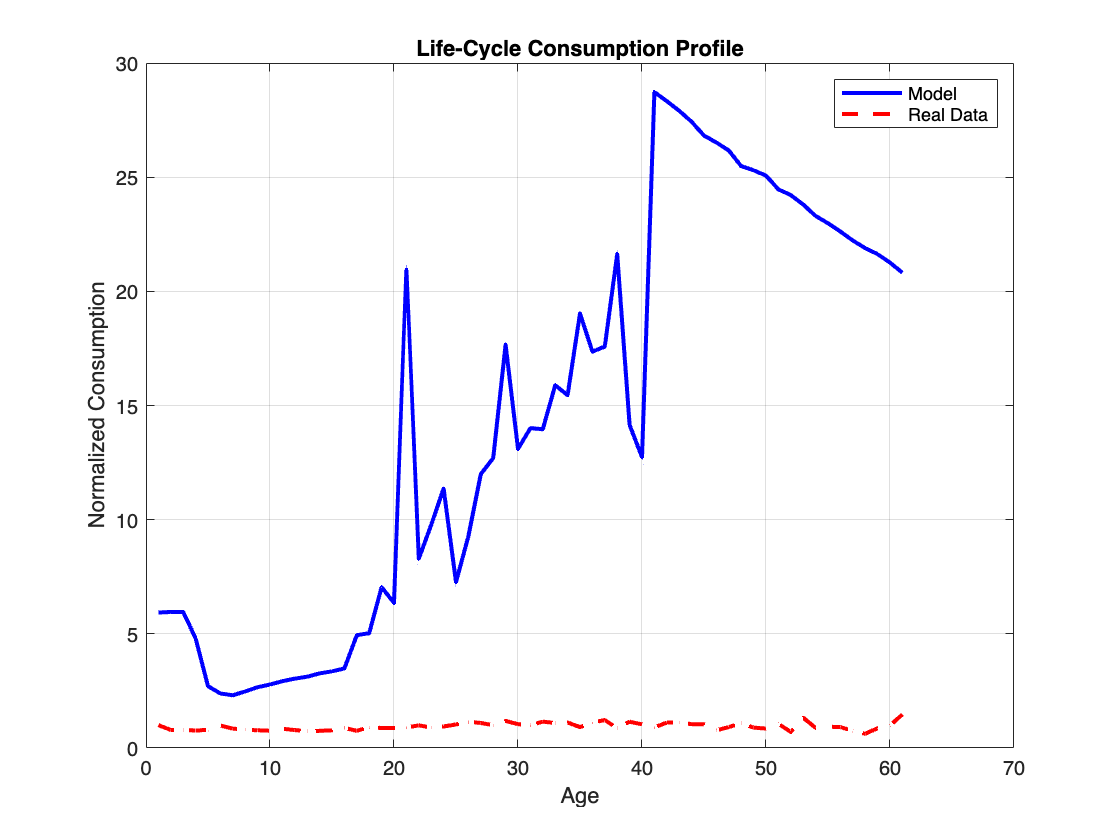

sim = simulate.lc(par0, sol);

ages_model = (1:par0.T)';

lcp_c = nan(par0.T,1);
lcp_a = nan(par0.T,1);
lcp_n = nan(par0.T,1);

for t = 1:par0.T
    lcp_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
    lcp_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
    lcp_n(t) = mean(sim.nsim(sim.tsim == t), 'omitnan');
end
figure;
plot(ages_model, lcp_c, 'b-', 'LineWidth', 2); hold on;
plot(ages_real_trimmed, cons_real_trimmed, 'r--', 'LineWidth', 2);
xlabel('Age'); ylabel('Normalized Consumption');
legend('Model', 'Real Data');
title('Life-Cycle Consumption Profile');
grid on;

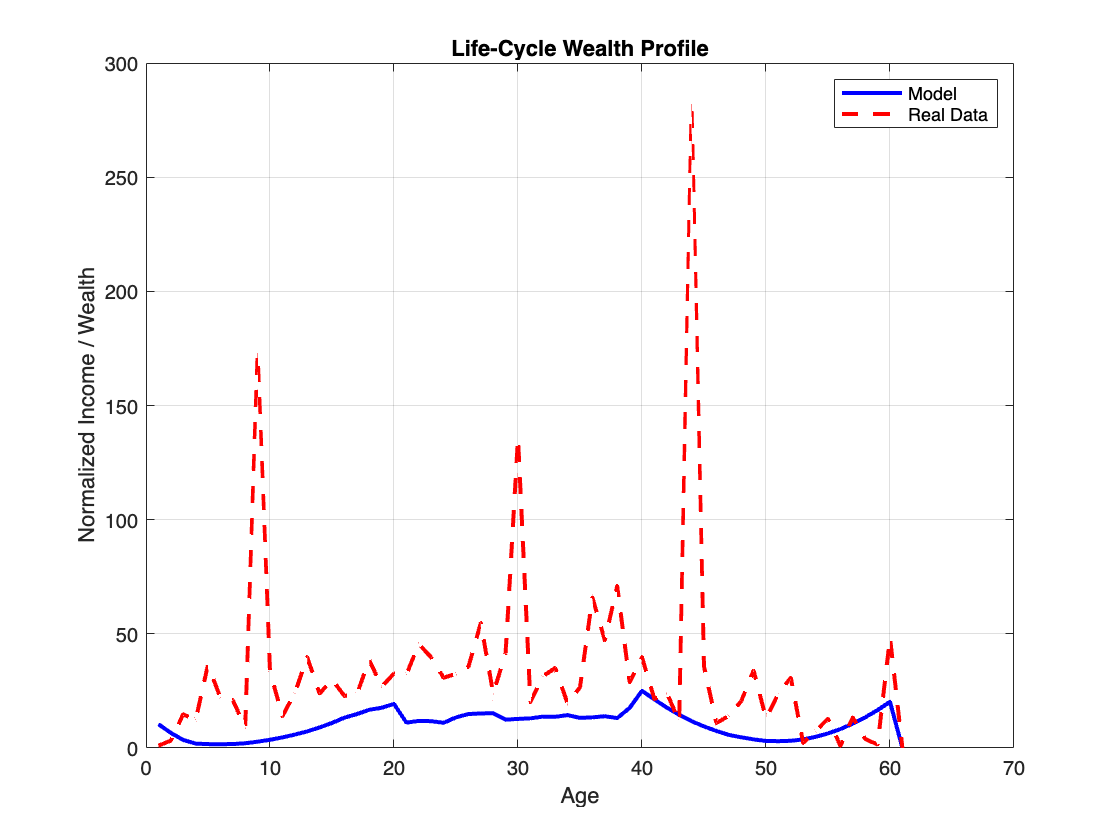


figure;
plot(ages_model, lcp_a, 'b-', 'LineWidth', 2); hold on;
plot(ages_real_trimmed, wealth_real_trimmed, 'r--', 'LineWidth', 2);
xlabel('Age'); ylabel('Normalized Income / Wealth');
legend('Model', 'Real Data');
title('Life-Cycle Wealth Profile');
grid on;

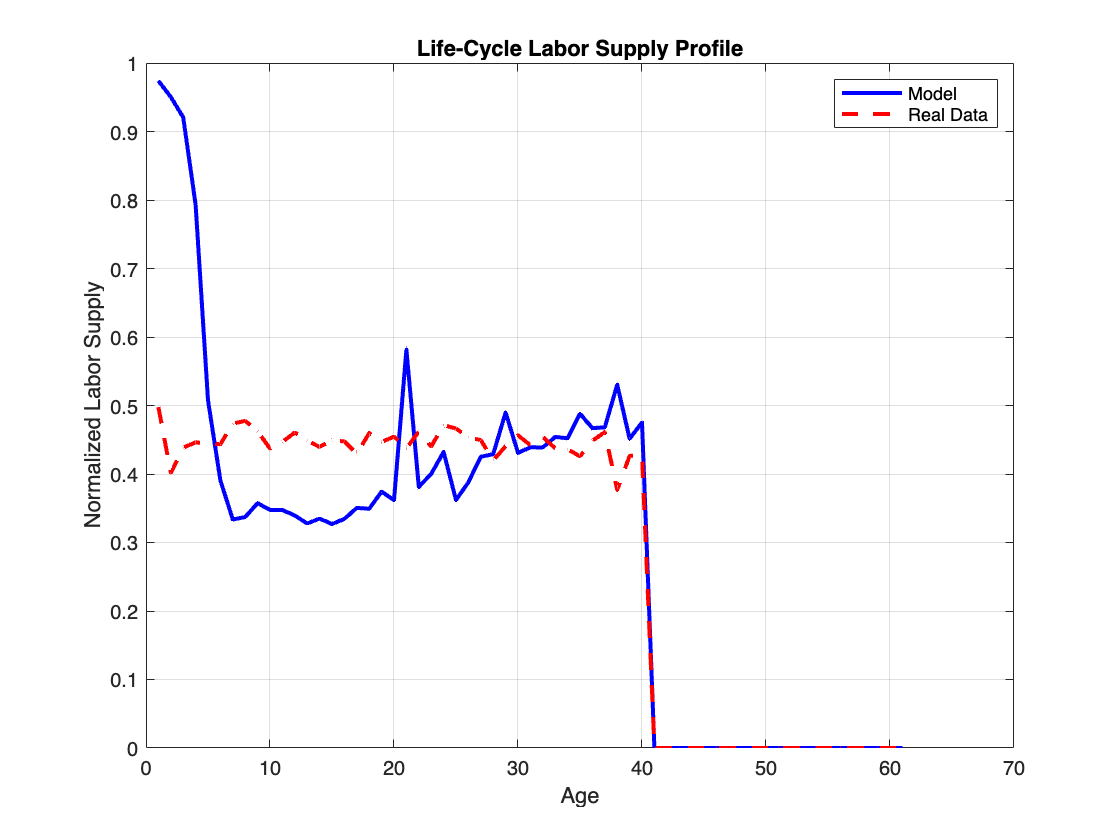


figure;
plot(ages_model, lcp_n, 'b-', 'LineWidth', 2); hold on;
plot(ages_real_trimmed, labor_real_trimmed, 'r--', 'LineWidth', 2);
xlabel('Age'); ylabel('Normalized Labor Supply');
legend('Model', 'Real Data');
title('Life-Cycle Labor Supply Profile');
grid on;